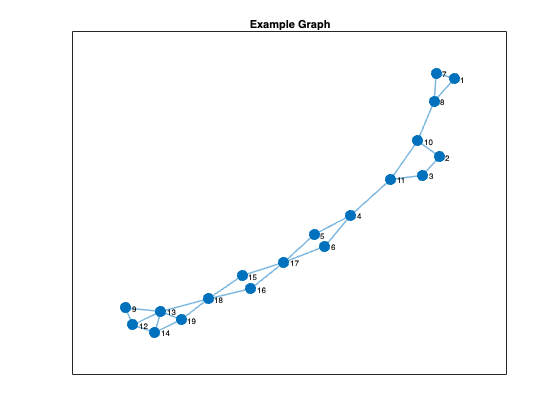

% load the data 
load('A.mat')

% plot the graph
p = plot(graph(A));
p.MarkerSize = 10;
p.LineWidth = 1.5;
title('Example Graph');

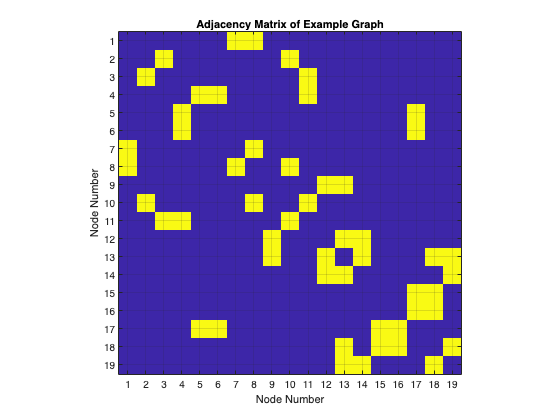

imagesc(A); %useful function for visualizing large matrices
xlabel('Node Number');
ylabel('Node Number');
set(gca,'Xtick',0:length(A));
set(gca,'Ytick',0:length(A));
grid on;
title('Adjacency Matrix of Example Graph');
axis square;

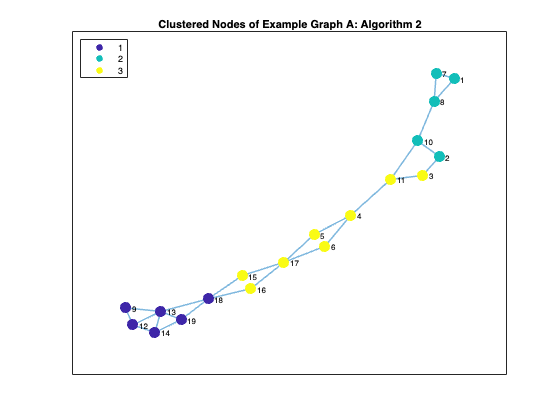

% run MATLAB spectral clustering
k = 3;
clusters = spectralcluster(A, k, 'Distance','precomputed');

% generate k colors
colors = parula(k);

% plot the graph 
p = plot(graph(A));
p.MarkerSize = 10;
p.LineWidth = 1.5;
title('Clustered Nodes of Example Graph A: Algorithm 2')
hold on;

% change to the node color according to the cluster ID
for i=1:length(clusters)
    clusterId = clusters(i);
    coloring = colors(clusterId, :);
    highlight(p, i, 'NodeColor', coloring);
end 

labels = strings(k, 1);
% create a "dummy" legend
for i=1:length(colors)
    coloring = colors(i, :);
    p(i) = plot(NaN,NaN,'or', 'MarkerFaceColor', coloring, 'MarkerEdgeColor', coloring);
    labels(i) = i;
end 

legend(p, labels,'Location','northwest');
hold off;

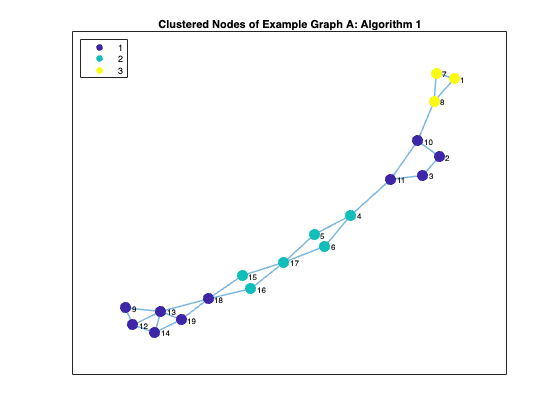

% example for algorithm 1
k = 3;

% compute the unnormalized L
D = diag(sum(A));
L = D - A;

% get the matrix uk from the k columns of u (eigenvectors)
[u, ~] = eig(L);
uk = u(:, 2:k+1);
clusters = kmeans(uk, k);

% generate k colors
colors = parula(k);

% plot the graph 
p = plot(graph(A));
p.MarkerSize = 10;
p.LineWidth = 1.5;
title('Clustered Nodes of Example Graph A: Algorithm 1')
hold on;

% change to the node color according to the cluster ID
for i=1:length(clusters)
    clusterId = clusters(i);
    coloring = colors(clusterId, :);
    highlight(p, i, 'NodeColor', coloring);
end 

labels = strings(k, 1);
% create a "dummy" legend
for i=1:length(colors)
    coloring = colors(i, :);
    p(i) = plot(NaN,NaN,'or', 'MarkerFaceColor', coloring, 'MarkerEdgeColor', coloring);
    labels(i) = i;
end 

legend(p, labels,'Location','northwest');
hold off;

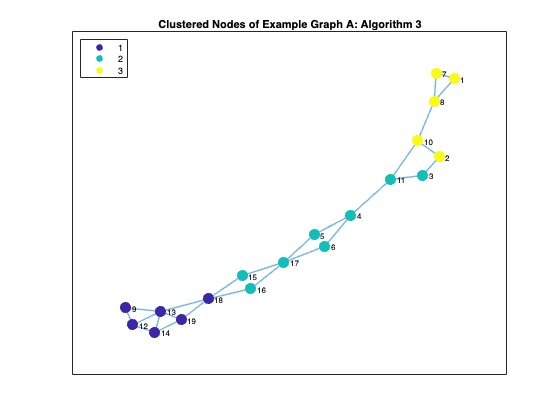

% Assuming you already have the adjacency matrix A
% Compute the normalized Laplacian matrix L
D = diag(sum(A));
D_sqrt_inv = diag(1./sqrt(diag(D)));
L = eye(size(A)) - D_sqrt_inv * A * D_sqrt_inv;
k=3;

% Step 1: Compute the first k eigenvectors of L
[V, D] = eig(L);
[~, idx] = sort(diag(D)); % sort eigenvalues in ascending order
Uk = V(:, idx(1:k)); % take the first k eigenvectors

% Step 2: Normalize each row of Uk to unit length to get Yk
Yk = bsxfun(@rdivide, Uk, sqrt(sum(Uk.^2, 2)));

% Step 3: Each row i of Yk is the feature vector fi in R^k
% This step is implicitly done because Yk's rows serve as feature vectors

% Step 4: Run k-means clustering on the rows of Yk
clusters = kmeans(Yk, k);

% Visualizing the clusters as before:

% generate k colors
colors = parula(k);

% plot the graph 
p = plot(graph(A));
p.MarkerSize = 10;
p.LineWidth = 1.5;
title('Clustered Nodes of Example Graph A: Algorithm 3')
hold on;

% change to the node color according to the cluster ID
for i=1:length(clusters)
    clusterId = clusters(i);
    coloring = colors(clusterId, :);
    highlight(p, i, 'NodeColor', coloring);
end 

labels = strings(k, 1);
% create a "dummy" legend
for i=1:length(colors)
    coloring = colors(i, :);
    p(i) = plot(NaN,NaN,'or', 'MarkerFaceColor', coloring, 'MarkerEdgeColor', coloring);
    labels(i) = i;
end 

legend(p, labels,'Location','northwest');
hold off;

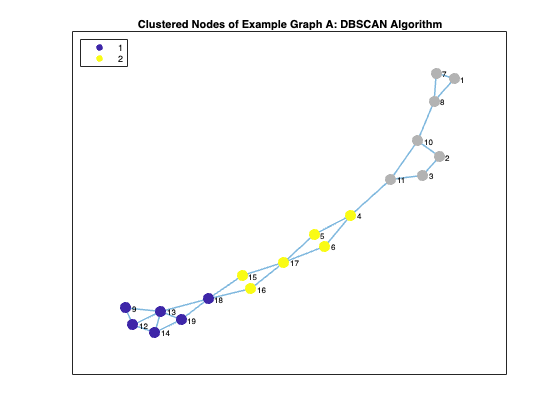

% Assuming the previous steps and you have the feature matrix Yk
minPts = 5;  % You can tune this parameter
epsilon = 0.5;  % You can tune this parameter as well

clusters = dbscan(Yk, epsilon, minPts);

% Find the number of unique clusters (excluding noise)
uniqueClusters = unique(clusters);
numClusters = length(uniqueClusters) - any(clusters == -1);  % -1 indicates noise in DBSCAN

% Generate colors
colors = parula(numClusters);

% Plot the graph
p = plot(graph(A));
p.MarkerSize = 10;
p.LineWidth = 1.5;
title('Clustered Nodes of Example Graph A: DBSCAN Algorithm')
hold on;

% Change node color according to the cluster ID
for i = 1:length(clusters)
    clusterId = clusters(i);
    if clusterId == -1  % Noise
        coloring = [0.7 0.7 0.7];  % Grey color for noise
    else
        coloring = colors(clusterId, :);
    end
    highlight(p, i, 'NodeColor', coloring);
end

labels = strings(numClusters, 1);
% Create a "dummy" legend
for i = 1:numClusters
    coloring = colors(i, :);
    p(i) = plot(NaN, NaN, 'or', 'MarkerFaceColor', coloring, 'MarkerEdgeColor', coloring);
    labels(i) = i;
end

legend(p, labels, 'Location', 'northwest');
hold off;